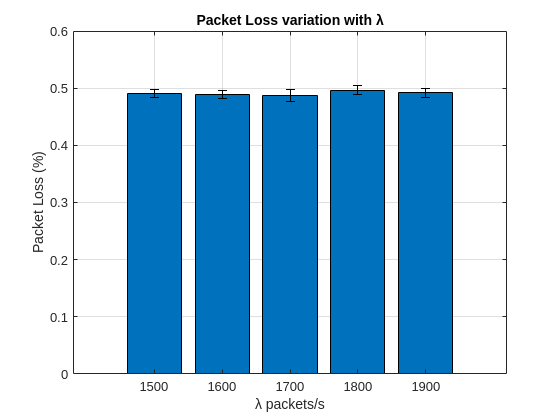

% a

N = 20; % number of simulator runs

lambda = [1500 1600 1700 1800 1900]; % values of lambda to test

results = zeros(length(lambda), 4, 2); % create matrix to store results

C = 10;         % Link Cpacity (mbps)
f = 1000000;    % Queue size in bytes
P = 100000;     % Number of packets to stop simulation
b = 10^-6;      % Bit-Error-Rate (ber)
alfa = 0.1;     % 1 - confidence_interval

for l=1:length(lambda)
    tmp = zeros(4, N); % create matrix to store results

    % run simulation N times and store in tmp
    for i=1:N
        [tmp(1, i), tmp(2, i), tmp(3, i), tmp(4, i)] = Simulator2(lambda(l), C, f, P, b);
    end

    % calculate mean and confidence interval from tmp and store in results
    % results(x, y, 1) is mean, results(x, y, 2) is confidence interval
    for i=1:4
        results(l, i, 1) = mean(tmp(i, :));
        results(l, i, 2) = norminv(1-alfa/2)*sqrt(var(tmp(i, :))/N);
    end
end

% Draw graph of packet loss variation with lambda
bar(lambda, results(:, 1, 1));
title("Packet Loss variation with λ");
xlabel("λ packets/s");
ylabel("Packet Loss (%)");
grid on;
hold on;
er = errorbar(lambda, results(:, 1, 1), results(:, 1, 2), results(:, 1, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;

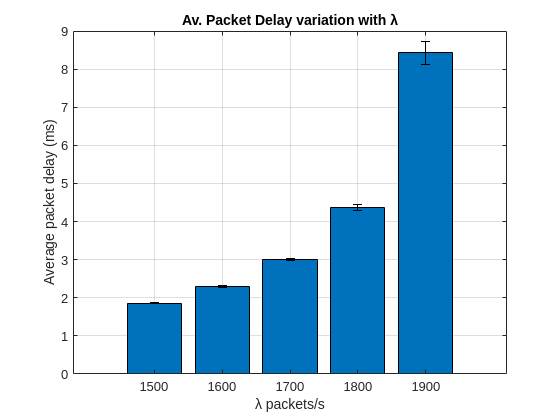


% Draw graph of packet delay variation with lambda
bar(lambda, results(:, 2, 1));
title("Av. Packet Delay variation with λ");
xlabel("λ packets/s");
ylabel("Average packet delay (ms)");
grid on;
hold on;
er = errorbar(lambda, results(:, 2, 1), results(:, 2, 2), results(:, 2, 2));
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
hold off;